# Final Project

## Paul Keene, Erica Lin

Dataset: Steinmetz, Zatka-Haas, Carandini & Harris 2019

## Setup

%set project directory (will need to change on different machine)
projDir = pwd;

%get session IDs and number
[sessionNames,nsesh] = getSessionNames(projDir);

%load the data from the raw files
[beh,eye] = loadData(sessionNames,nsesh,projDir);
load('sorted_data/neural/spikes.mat');

% load paths for functions
visualization_path = [pwd,'/visualize']; 
addpath(visualization_path);
analysis_path = [pwd,'/analysis']; 
addpath(analysis_path);

## Visualization

% Plot Raster for motor neuron activity during response to left vs right vs neutral trials
fprintf("MOs neuron activity during response to left vs right vs neutral trials:")
raster_subject1_directional(beh, spikes)
fprintf("For the neutral stimuli, there is more neural activity at the response time, compared to when there was a clear left or right stimuli.")

% Plot ISI for visual neuron activity during stimulus of high, medium, and no
% difference between right and left
fprintf("VISp neuron activity during stimulus of high, medium, and no difference between right and left:")

VISp neuron activity during stimulus of high, medium, and no difference between right and left:

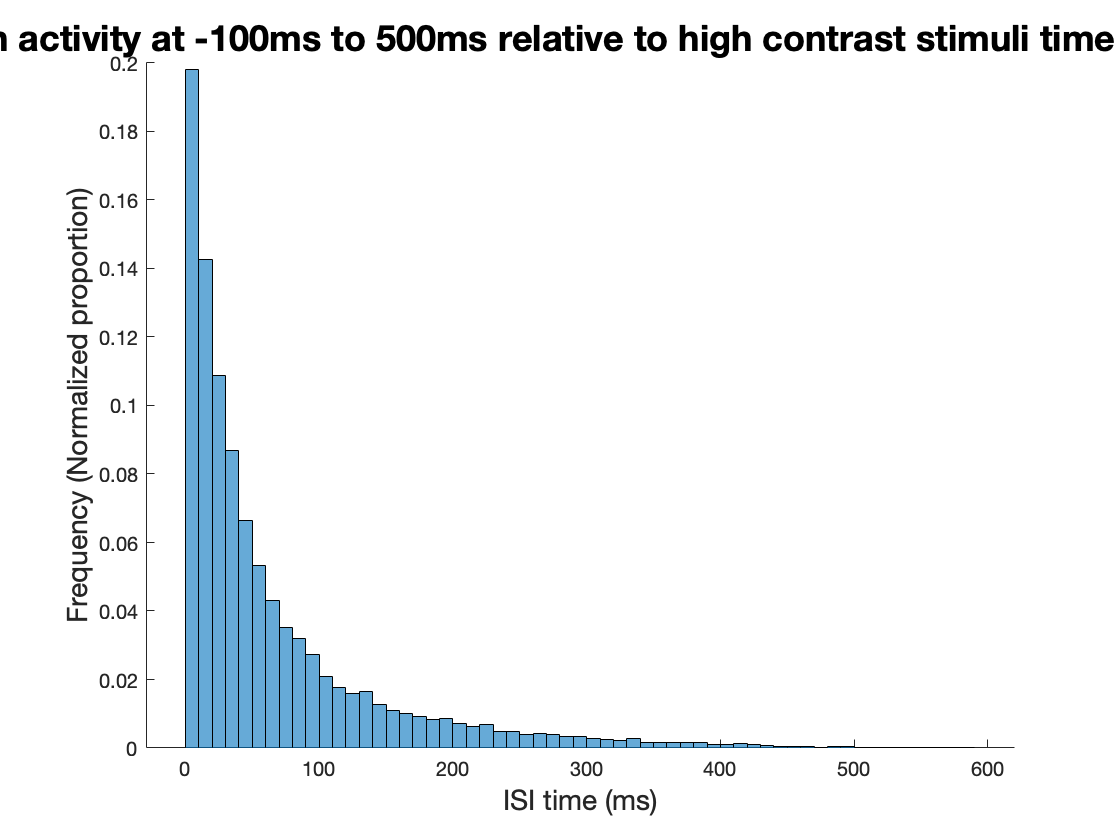

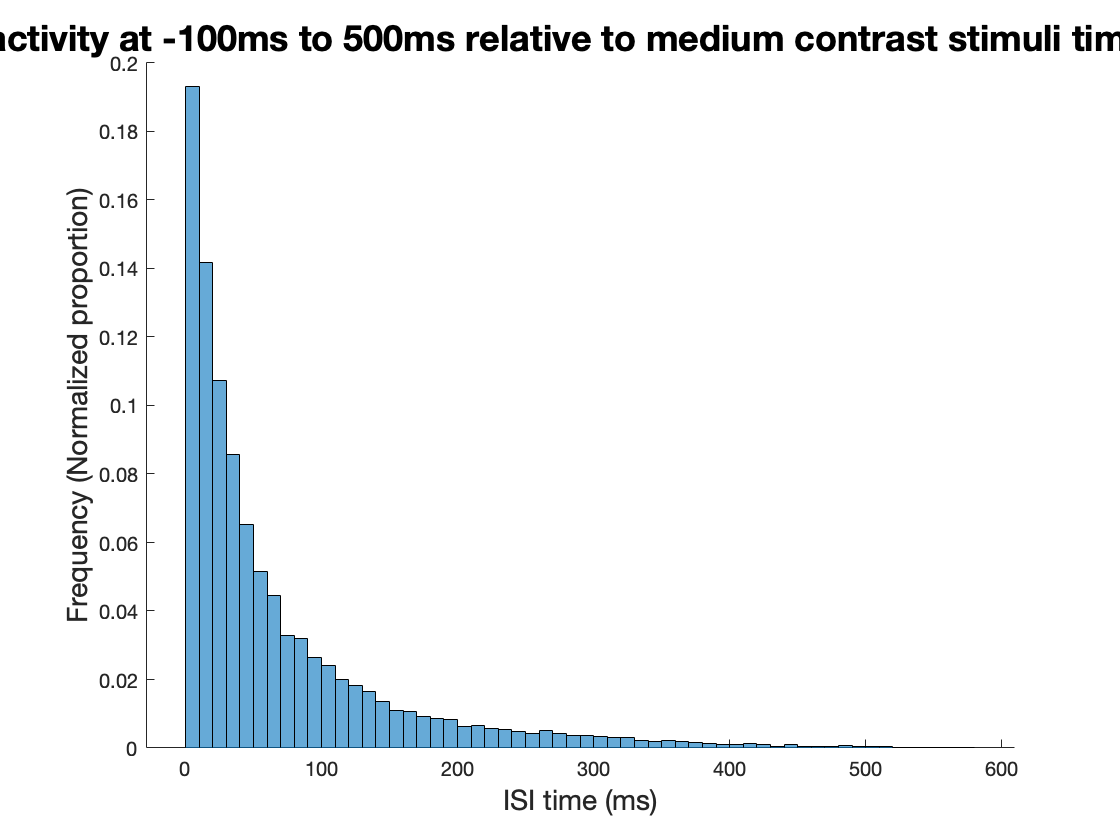

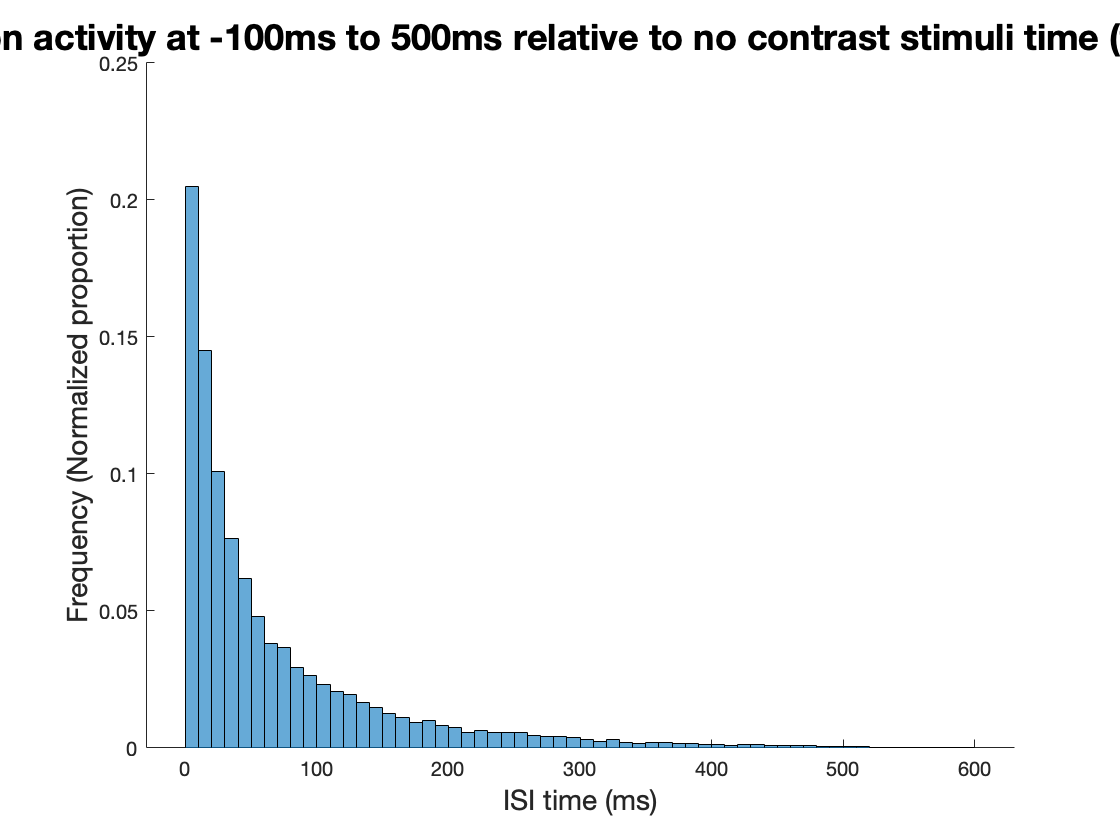

isi_subject1_contrast(beh, spikes)

fprintf("The ISI for high and medium differences between left/right are very similar. When there is no difference between left/right, there are relatively more interspike intervals on the shorter side -- there is more frequent spiking of the visual neuron when there is no difference between left/right.")

% visualize gaze after stimulus appears
gaze_tracking()